# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment. The types of data we will convert are:

- Voltage recording

- Local field potential (LFP)

- Spike times

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', ['Mouse5_Day3'], ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'general_experimenter', 'My Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                        file_create_date: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: 2018-04-25T02:30:03.000000-04:00
                               timestamps_reference_time: []
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [0×1 types.untyped.Set]
                          general_experiment_description: []
               

## Extracellular electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in a `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group.

## Electrode table

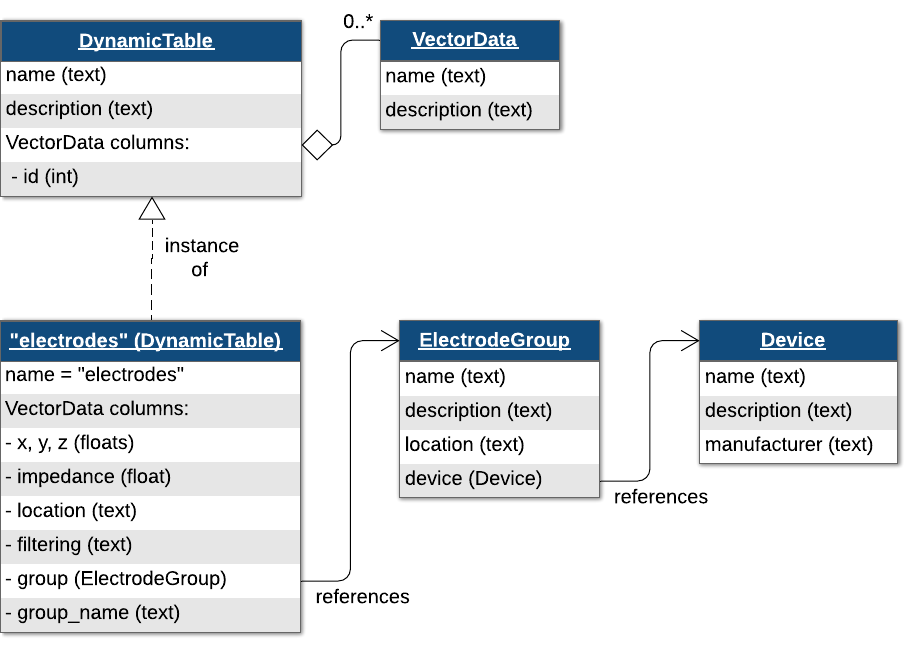

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

Here, we also demonstate another method for creating `DynamicTable`s, by first creating a MATLAB native `Table` object and then calling `util.table2nwb` to convert this `Table` object into a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html).

nshanks = 4;
nchannels_per_shank = 3;
variables = {'location', 'group', 'label'};
tbl = cell2table(cell(0, length(variables)), 'VariableNames', variables);
device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', device);
for ishank = 1:nshanks
    electrode_group = types.core.ElectrodeGroup( ...
        'description', ['electrode group for shank' num2str(ishank)], ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(device) ...
    );
    nwb.general_extracellular_ephys.set(['shank' num2str(ishank)], electrode_group);
    group_object_view = types.untyped.ObjectView(electrode_group);
    for ielec = 1:nchannels_per_shank
        electrode_label = ['shank' num2str(ishank) 'elec' num2str(ielec)];
        tbl = [tbl; {'unknown', group_object_view, electrode_label}];
    end
end
tbl

tbl = 12×3 table
     location                 group                     label     
    ___________    ____________________________    _______________

    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1elec1'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1elec2'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1elec3'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2elec1'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2elec2'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2elec3'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3elec1'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3elec2'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3elec3'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank4elec1'}
    {'unknown'}    1×1 types.untyped.ObjectView    {'shank4elec2'}
    {'unk

electrode_table = util.table2nwb(tbl, 'all electrodes');
nwb.general_extracellular_ephys_electrodes = electrode_table;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrode_table), ...
    'description', 'all electrodes', ...
    'data', (0:height(tbl)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

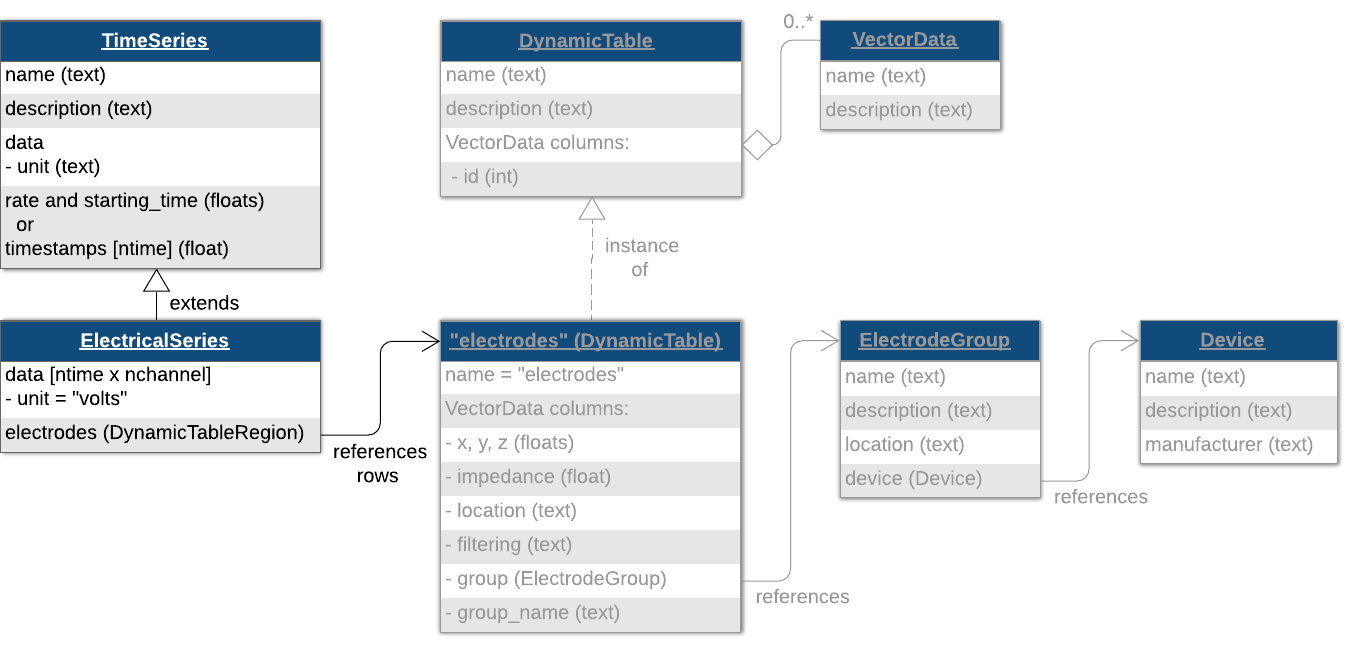

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` earlier.

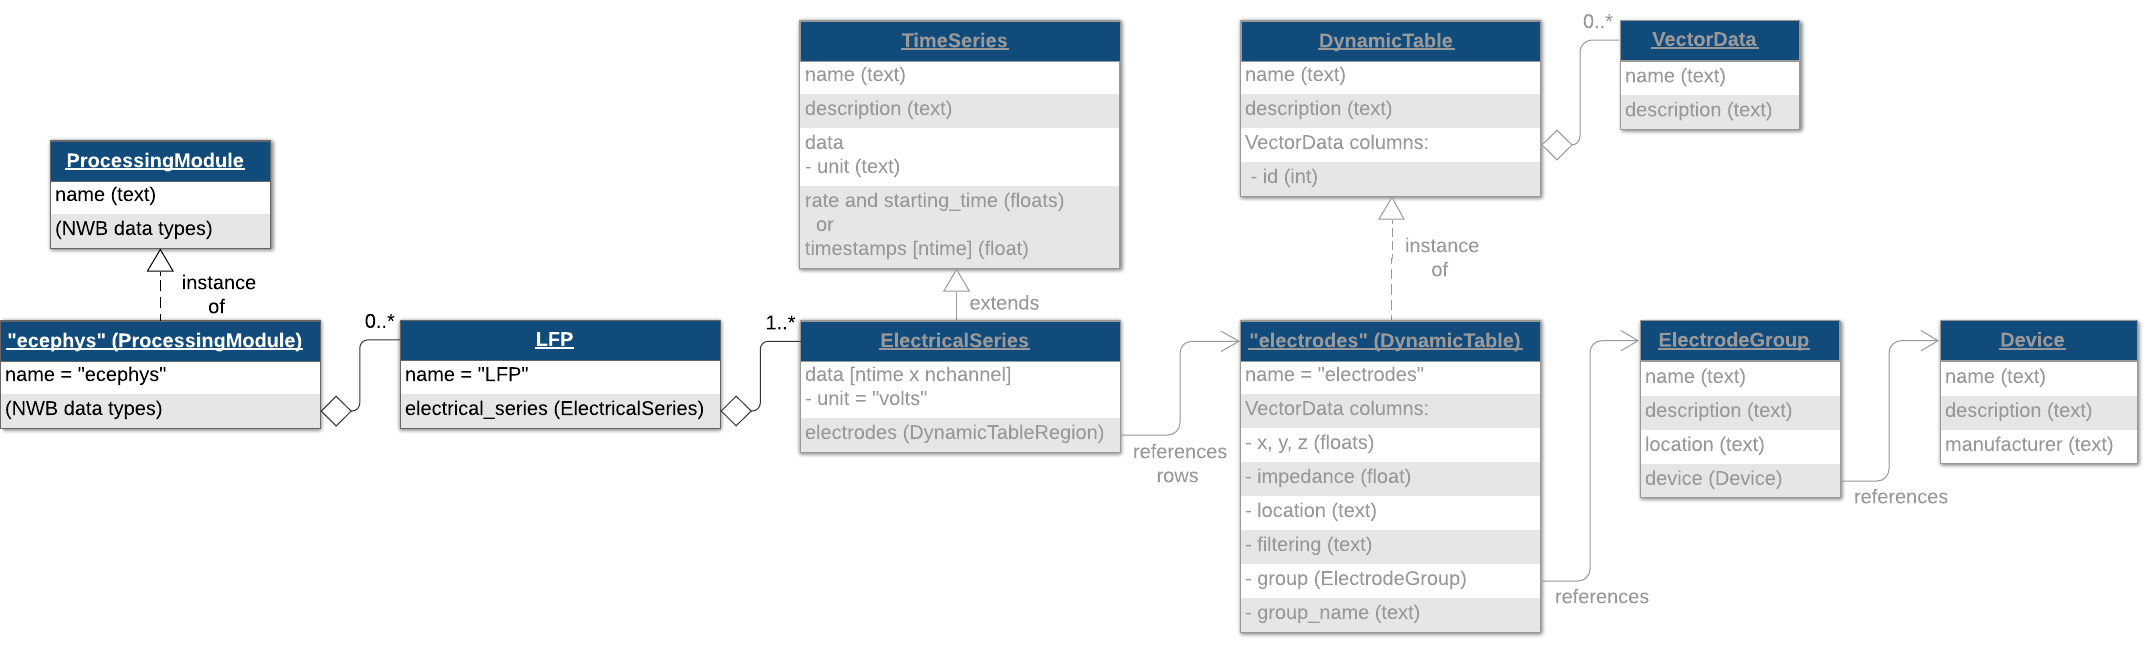

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

## Spike times

#### Ragged arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default `Units` table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for ishank = 1:num_cells
    spikes{ishank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.6396 0.2896 0.0314 0.9221 0.3407 0.5469 0.5757 0.5082 0.2912 0.2553 0.4483 0.8784 0.9697 0.0504 0.5716 0.2253 0.2116 0.5906 0.5342 0.6822 0.7766 0.7228]}    {[0.6728 0.3365 0.9754 0.8702 0.8288 0.9480 0.2605 0.6411 0.0698 0.4599 0.1253 0.0492 0.8847 0.5803 0.2275 0.7173 0.9345 0.4235 0.4303 0.6187 0.6714 0.2941 0.2859]}    {[0.3792 0.7001 0.1283 0.0742 0.0898 0.6241 0.6173 0.3377 0.6668 0.3677 0.9807 0.5117 0.3528 0.6892 0.6278 0.9965]}    {[0.7635 0.8786 0.9877 0.8399 0.9498 0.3509 0.5343 0.3758 0.6318 0.9983 0.5630 0.0420 0.7779 0.1430 0.2081 0.3537 0.3288 0.5830 0.3741 0.9639 0.9662 0.4215 0.3803 0.6258 0.1987 0.8101 0.7438 0.2577]}    {[0.8252 0.2577 0.1224 0.7139 0.8254 0.9654 0.5946 0.6366 0.9655 0.5666 0.0648 0.0511 0.8503 0.8824 0.9462 0.9233 0.3797 0.8714 0.5761]}    {[0.9929 0.8924 0.0210 0.4232 0.8338 0.6511 0.4199 0.7503 0.0680 0.3553 0.9576 0.9398 0.4434 0.0800 0.3693 0.0484 0.3977 0.4624]}    {[0.3560 0.7936 0.9937 0.8962 0.1264 0.4553 0.0

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

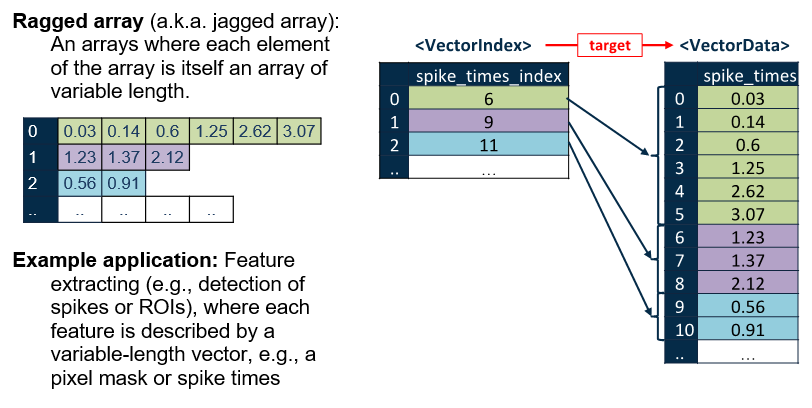

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64(0:length(spikes) - 1) ...
    ), ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

## Write the file

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing data regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =     1.8304    1.2008    1.9150   -0.9461    0.8865    0.5297    0.4089    0.2502   -0.6511   -0.1110
    1.5834   -0.7822   -2.0870    0.9602   -1.1554    2.4135   -2.0341   -1.8944    1.1283   -0.9568
    0.9441   -1.3912    0.0778   -0.8608   -0.8931    1.3274   -0.6456    0.2910   -0.0223    0.9700
    0.0444   -0.1118    1.0166    0.4426    0.0037   -0.2980   -0.7820   -1.0702    1.2701   -1.9685
    1.7349   -2.1653   -0.2573    0.0468   -0.6464    1.6677   -1.0712   -0.3163    0.0232    0.3386



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.6396
    0.2896
    0.0314
    0.9221
    0.3407
    0.5469
    0.5757
    0.5082
    0.2912
    0.2553


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)